# Inputs

file_name_inp = 'mesh3D_quadratic1.inp'

file_name_inp = 'mesh3D_quadratic1.inp'

elemType = 'H10'

elemType = 'H10'

mesh_correction_type = 2

mesh_correction_type = 2

dim = 3

dim = 3

## Mesh from ABAQUS, read and update

[node, element, bdy_node, bdy_elem] = read_mesh_abaqus(file_name_inp,elemType,mesh_correction_type)

node =    20.0000         0         0
         0         0         0
         0   20.0000         0
         0         0   20.0000
   14.1421   14.1421         0
   14.1421         0   14.1421
         0   14.1421   14.1421
         0    7.0711    7.0711
    7.0711         0    7.0711
    8.1650    8.1650   16.3299


element =      7     6     2     5    10     9     8    12    11    13
     7     2     3     5     8    15    14    12    13    16
     7     6     4     2    10    18    17     8     9    19
     6     5     1     2    11    21    20     9    13    22


bdy_node =      1     3     4     5     6     7    10    11    12    14    16    17    18    20    21


bdy_elem =      1     2     3     4


## Plot the mesh

plot_mesh(node,element,elemType,'b*-')
ndof= size(node,1)    % number of nodes

ndof = 22

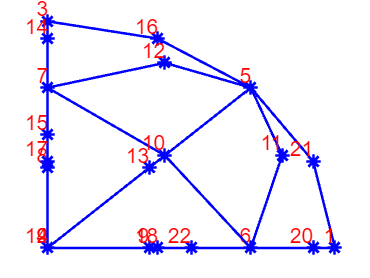



% Adding node numbers as text at each node's location
if dim == 2
    for i = 1:ndof
        text(node(i, 1), node(i, 2), num2str(i), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'r');
    end
elseif dim == 3
    for i = 1:ndof
        text(node(i, 1), node(i, 2),node(i,3), num2str(i), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'Color', 'r');
    end 
else
    warning('dimension not valid')
end

## Saving .png output file

% % Save the figure as a .png file
% saveas(gcf, '3D_quad_mesh1.png');
